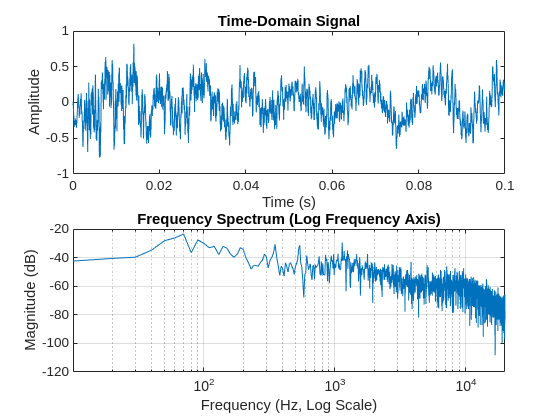

% Load the WAV file
[signal, fs] = audioread('in_100ms_mono.wav'); % signal is the audio data, fs is the sample rate

% Plot the time-domain signal
t = (0:length(signal)-1) / fs;
figure;
subplot(2,1,1);
plot(t, signal);
xlabel('Time (s)');
ylabel('Amplitude');
title('Input Time-Domain Signal');

% Compute and plot the spectrum with log frequency axis
n = length(signal);
frequencies = (0:n-1) * (fs/n); 
spectrum = fft(signal);
magnitude_dB = 20 * log10(abs(spectrum) / n); % Magnitude in dB

% Plot using a logarithmic frequency axis
subplot(2,1,2);
semilogx(frequencies(1:floor(n/2)), magnitude_dB(1:floor(n/2)));
xlim([0,20000]);
xlabel('Frequency, Hz');
ylabel('Magnitude (dB)');
title('Input Frequency Spectrum');
grid;

% Load the WAV file
[signal, fs] = audioread('out.wav'); % signal is the audio data, fs is the sample rate

Error using audioread (line 154)
The file type is not supported


% Plot the time-domain signal
t = (0:length(signal)-1) / fs;
figure;
subplot(2,1,1);
plot(t, signal);
xlabel('Time (s)');
ylabel('Amplitude');
title('Output Time-Domain Signal');

% Compute and plot the spectrum with log frequency axis
n = length(signal);
frequencies = (0:n-1) * (fs/n); 
spectrum = fft(signal);
magnitude_dB = 20 * log10(abs(spectrum) / n); % Magnitude in dB

% Plot using a logarithmic frequency axis
subplot(2,1,2);
semilogx(frequencies(1:floor(n/2)), magnitude_dB(1:floor(n/2)));
xlim([0,20000]);
xlabel('Frequency Hz');
ylabel('Magnitude (dB)');
title('Output Frequency Spectrum');
grid;